*ODE solution*

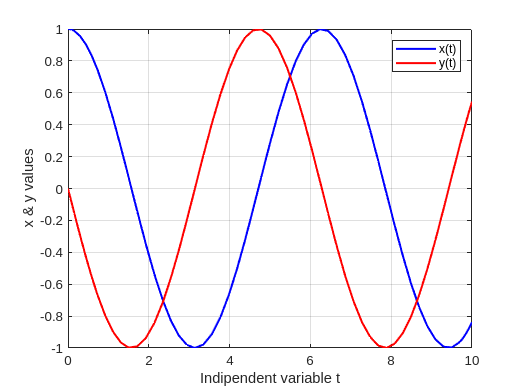

%BASIC ODE SOLUTION
% x' = y
% y' = -x
% x0 = 1
% y0 = 0
% x = cos(t)
% y = sin(t)

% z' = F(t, z) = (Z(z) -Z(1)) where z = (x y)
function dzdt = ODE(t, z)
    x = z(1);
    y = z(2);
    dzdt = [y; -x];
end

% Time range
tspan = [0 10]; 
z0 = [1; 0];

% Risoluzione con ode45
[t, z] = ode45(@ODE, tspan, z0);

% Estrazione delle soluzioni
x = z(:, 1);
y = z(:, 2);

% Plot della soluzione
figure;
plot(t, x, 'b', 'LineWidth', 1.5); hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
legend('x(t)', 'y(t)');
xlabel('Indipendent variable t');
ylabel('x & y values');
grid on;

*Explicit Euler solution with h = 1/10*

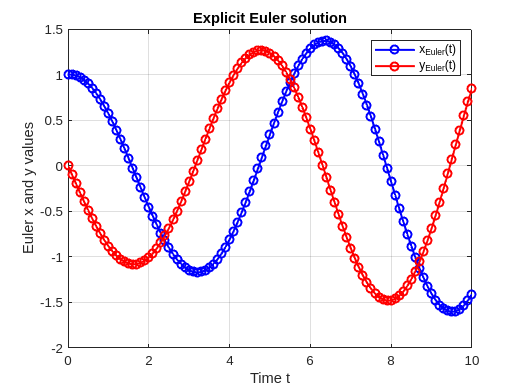

% EXPLICIT EULER IMPLEMENTATION
h = 1/10; %passo
t_euler = 0:h:10; 
N = length(t_euler);
z_euler = zeros(2, N);
z_euler(:, 1) = z0; % initial cond

for i = 1:N-1
    z_euler(:, i+1) = z_euler(:, i) + h * ODE(t_euler(i), z_euler(:, i));
end

x_euler = z_euler(1, :);
y_euler = z_euler(2, :);

figure;
plot(t_euler, x_euler, 'b-o', 'LineWidth', 1.5); hold on;
plot(t_euler, y_euler, 'r-o', 'LineWidth', 1.5);
legend('x_{Euler}(t)', 'y_{Euler}(t)');
xlabel('Time t');
ylabel('Euler x and y values');
title('Explicit Euler solution');
grid on;


% L'Euler Esplicito è semplice da implementare,
% ma ha una precisione relativamente bassa (errore proporzionale a hh),
% quindi per passi troppo grandi può diventare instabile. 
% In confronto, ode45 usa un metodo Runge-Kutta adattivo, che è molto
% più preciso e stabile.


This is the prof. Bertolazzi solution, he uses many Matlab tricks, like @ and others. In the plot he wants to plot als o the circle. The circle is the analytical solution and the other one is the Euler method solution which is less precise and diverges. The Euler solution is like a spiral which opens with respect to the starting circle which is the analytical solution.

% PROF SOLUTION
ODE = @(t, z) [Z(2); -Z(1)]; %inline function of matlab (@)

Declaring a variable with the same name as the local function "ODE" is not supported in scripts.

Z0 = [1;0];
options = odeset('RelTol', 1e-2, 'Stats','on');

n_interval = 1000;
T_max = 10;
tspan = 0 : T_max / n_interval : T_max;

%solve ode
[t, zsol] = ode45(ODE, tspan, Z0, options);

%plot
hold off;


% Euler explicit
Z = Z0; %matrix whose columns are the solution
t = 0;
dt = 1/10;
while t(end) < T_max
    Z(:, end+1) = Z(:, end) + dt * ODE(t(end), Z(:, end));
    t(end + 1) = t(end) + dt;
end

hold off;


we can use the same script in order to create the van der pool oscillator, but larger tolerances, check prof script

% SOLVE THE ODE OF VAN DER POOL
% x' = y
% y' = 1000*(1-x^2)*y - x

% same script of before but larger tolerance
n_interval = 1000;
T_max = 3000;